# **2D Reinforced Concrete Frame Pushover Analysis**

This live script is written as a guided walkthrough for a structural-analysis example. It walks from model definition to analysis setup and then to response checks or plots. Read the text cells first, then run each code cell in order so that the variables, model state, and recorded results are available for the later sections.

clear; clc;

First, instantiate the OpenSeesMatlab interface class. This class provides native OpenSees commands, as well as additional visualization, pre/post-processing, and utility methods.

opsMat = OpenSeesMatlab();
ops = opsMat.opensees;

### `Start of model generation`

This section creates the finite-element idealization used by the rest of the example. Check the dimensions, tags, and connectivity here before moving on.

ops.wipe();

% set modelbuilder
ops.model('basic', '-ndm', 2, '-ndf', 3);

%% ############################################
%  Units and Constants
%  ############################################
inch = 1.0;
kip  = 1.0;
sec  = 1.0;

% Dependent units
sq_in = inch * inch;
ksi   = kip / sq_in;
ft    = 12.0 * inch;

% Constants
g  = 386.2 * inch / (sec * sec);
pi_val = acos(-1); % #ok<NASGU>

%% #######################################
%  Dimensions
%  #######################################
% Dimensions Input
H_story   = 10.0 * ft;
W_bayX    = 16.0 * ft;
W_bayY_ab = 5.0 * ft + 10.0 * inch;
W_bayY_bc = 8.0 * ft +  4.0 * inch;
W_bayY_cd = 5.0 * ft + 10.0 * inch;

% Calculated dimensions
W_structure = W_bayY_ab + W_bayY_bc + W_bayY_cd; % #ok<NASGU>

%% ################
%  Material
%  ################
matTag    = 1;
matConnAx = 2; % #ok<NASGU>
matConnRot= 3; % #ok<NASGU>

Fy = 60.0 * ksi;     % Yield stress
Es = 29000.0 * ksi;  % Modulus of Elasticity of Steel
v  = 0.2;            % Poisson's ratio
Gs = Es / (1 + v);   % Shear modulus
b  = 0.10;           % Strain hardening ratio

R0      = 18.0;
cR1     = 0.925;
cR2     = 0.15;
a1      = 0.05;
a2      = 1.00;
a3      = 0.05;
a4      = 1.0;
sigInit = 0.0;
alpha   = 0.05; % #ok<NASGU>

ops.uniaxialMaterial('Steel02', matTag, Fy, Es, b, R0, cR1, cR2, ...
    a1, a2, a3, a4, sigInit);

%% ##################
%  Sections
%  ##################
colSecTag1  = 1;
colSecTag2  = 2;
beamSecTag1 = 3;
beamSecTag2 = 4;
beamSecTag3 = 5;

% COMMAND: section('WFSection2d', secTag, matTag, d, tw, bf, tf, Nfw, Nff)

ops.section('WFSection2d', colSecTag1,  matTag, 10.5*inch, 0.26*inch, 5.77*inch, 0.44*inch, 15, 16); % outer Column
ops.section('WFSection2d', colSecTag2,  matTag, 10.5*inch, 0.26*inch, 5.77*inch, 0.44*inch, 15, 16); % inner Column

ops.section('WFSection2d', beamSecTag1, matTag, 8.3*inch, 0.44*inch, 8.11*inch, 0.685*inch, 15, 15); % outer Beam
ops.section('WFSection2d', beamSecTag2, matTag, 8.2*inch, 0.40*inch, 8.01*inch, 0.650*inch, 15, 15); % inner Beam
ops.section('WFSection2d', beamSecTag3, matTag, 8.0*inch, 0.40*inch, 7.89*inch, 0.600*inch, 15, 15); % inner Beam

% Beam size - W10x26
Abeam  = 7.61 * inch * inch; % #ok<NASGU>
IbeamY = 144.0 * (inch^4);   % #ok<NASGU>
IbeamZ = 14.1  * (inch^4);   % #ok<NASGU>

% BRB input data
Acore  = 2.25 * inch; % #ok<NASGU>
Aend   = 10.0 * inch; % #ok<NASGU>
LR_BRB = 0.55;        % #ok<NASGU>

%% ###########################
%  Nodes
%  ###########################
% Create all main nodes
ops.node(1,  0.0,      0.0);
ops.node(2,  W_bayX,   0.0);
ops.node(3,  2*W_bayX, 0.0);

ops.node(11, 0.0,      H_story);
ops.node(12, W_bayX,   H_story);
ops.node(13, 2*W_bayX, H_story);

ops.node(21, 0.0,      2*H_story);
ops.node(22, W_bayX,   2*H_story);
ops.node(23, 2*W_bayX, 2*H_story);

ops.node(31, 0.0,      3*H_story);
ops.node(32, W_bayX,   3*H_story);
ops.node(33, 2*W_bayX, 3*H_story);

% Beam connection nodes
ops.node(1101, 0.0,      H_story);
ops.node(1201, W_bayX,   H_story);
ops.node(1202, W_bayX,   H_story);
ops.node(1301, 2*W_bayX, H_story);

ops.node(2101, 0.0,      2*H_story);
ops.node(2201, W_bayX,   2*H_story);
ops.node(2202, W_bayX,   2*H_story);
ops.node(2301, 2*W_bayX, 2*H_story);

ops.node(3101, 0.0,      3*H_story);
ops.node(3201, W_bayX,   3*H_story);
ops.node(3202, W_bayX,   3*H_story);
ops.node(3301, 2*W_bayX, 3*H_story);

m5 = 5.0 / g;
m6 = 6.0 / g;

ops.mass(11, m5, m5, 0.0);
ops.mass(12, m6, m6, 0.0);
ops.mass(13, m5, m5, 0.0);

ops.mass(21, m5, m5, 0.0);
ops.mass(22, m6, m6, 0.0);
ops.mass(23, m5, m5, 0.0);

ops.mass(31, m5, m5, 0.0);
ops.mass(32, m6, m6, 0.0);
ops.mass(33, m5, m5, 0.0);

%% ###############
%  Constraints
% ###############
ops.fix(1, 1, 1, 1);
ops.fix(2, 1, 1, 1);
ops.fix(3, 1, 1, 1);

%% #######################
%  Elements
%  #######################
% Assign beam-integration tags
ColIntTag1  = 1;
ColIntTag2  = 2;
BeamIntTag1 = 3;
BeamIntTag2 = 4;
BeamIntTag3 = 5;

ops.beamIntegration('Lobatto', ColIntTag1,  colSecTag1,  4);
ops.beamIntegration('Lobatto', ColIntTag2,  colSecTag2,  4);
ops.beamIntegration('Lobatto', BeamIntTag1, beamSecTag1, 4);
ops.beamIntegration('Lobatto', BeamIntTag2, beamSecTag2, 4);
ops.beamIntegration('Lobatto', BeamIntTag3, beamSecTag3, 4);

% Assign geometric transformation
ColTransfTag = 1;
BeamTranfTag = 2;

ops.geomTransf('PDelta', ColTransfTag);
ops.geomTransf('Linear', BeamTranfTag);

% Assign elements
% Nonlinear column elements
ops.element('forceBeamColumn', 1,  1,  11, ColTransfTag, ColIntTag1, '-mass', 0.0);
ops.element('forceBeamColumn', 2,  2,  12, ColTransfTag, ColIntTag2, '-mass', 0.0);
ops.element('forceBeamColumn', 3,  3,  13, ColTransfTag, ColIntTag1, '-mass', 0.0);

ops.element('forceBeamColumn', 11, 11, 21, ColTransfTag, ColIntTag1, '-mass', 0.0);
ops.element('forceBeamColumn', 12, 12, 22, ColTransfTag, ColIntTag2, '-mass', 0.0);
ops.element('forceBeamColumn', 13, 13, 23, ColTransfTag, ColIntTag1, '-mass', 0.0);

ops.element('forceBeamColumn', 21, 21, 31, ColTransfTag, ColIntTag1, '-mass', 0.0);
ops.element('forceBeamColumn', 22, 22, 32, ColTransfTag, ColIntTag2, '-mass', 0.0);
ops.element('forceBeamColumn', 23, 23, 33, ColTransfTag, ColIntTag1, '-mass', 0.0);

% Main beam elements
ops.element('forceBeamColumn', 101, 1101, 1201, BeamTranfTag, BeamIntTag1, '-mass', 0.0);
ops.element('forceBeamColumn', 102, 1202, 1301, BeamTranfTag, BeamIntTag1, '-mass', 0.0);

ops.element('forceBeamColumn', 201, 2101, 2201, BeamTranfTag, BeamIntTag2, '-mass', 0.0);
ops.element('forceBeamColumn', 202, 2202, 2301, BeamTranfTag, BeamIntTag2, '-mass', 0.0);

ops.element('forceBeamColumn', 301, 3101, 3201, BeamTranfTag, BeamIntTag3, '-mass', 0.0);
ops.element('forceBeamColumn', 302, 3202, 3301, BeamTranfTag, BeamIntTag3, '-mass', 0.0);

% Rigid beam-column connections
ops.equalDOF(11, 1101, 1, 2, 3);
ops.equalDOF(12, 1201, 1, 2, 3);
ops.equalDOF(12, 1202, 1, 2, 3);
ops.equalDOF(13, 1301, 1, 2, 3);

ops.equalDOF(21, 2101, 1, 2, 3);
ops.equalDOF(22, 2201, 1, 2, 3);
ops.equalDOF(22, 2202, 1, 2, 3);
ops.equalDOF(23, 2301, 1, 2, 3);

ops.equalDOF(31, 3101, 1, 2, 3);
ops.equalDOF(32, 3201, 1, 2, 3);
ops.equalDOF(32, 3202, 1, 2, 3);
ops.equalDOF(33, 3301, 1, 2, 3);

%% ################
%  Gravity Load
%  ################
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

% Nodal loads
ops.load(11, 0.0, -5.0*kip, 0.0);
ops.load(12, 0.0, -6.0*kip, 0.0);
ops.load(13, 0.0, -5.0*kip, 0.0);

ops.load(21, 0.0, -5.0*kip, 0.0);
ops.load(22, 0.0, -6.0*kip, 0.0);
ops.load(23, 0.0, -5.0*kip, 0.0);

ops.load(31, 0.0, -5.0*kip, 0.0);
ops.load(32, 0.0, -6.0*kip, 0.0);
ops.load(33, 0.0, -5.0*kip, 0.0);

### Visualize the model

This section creates the finite-element idealization used by the rest of the example. Check the dimensions, tags, and connectivity here before moving on.

[OpenSeesMatlab] Model summary
  Nodes: 24
  Beam elements: 15
  MP constraints: 12


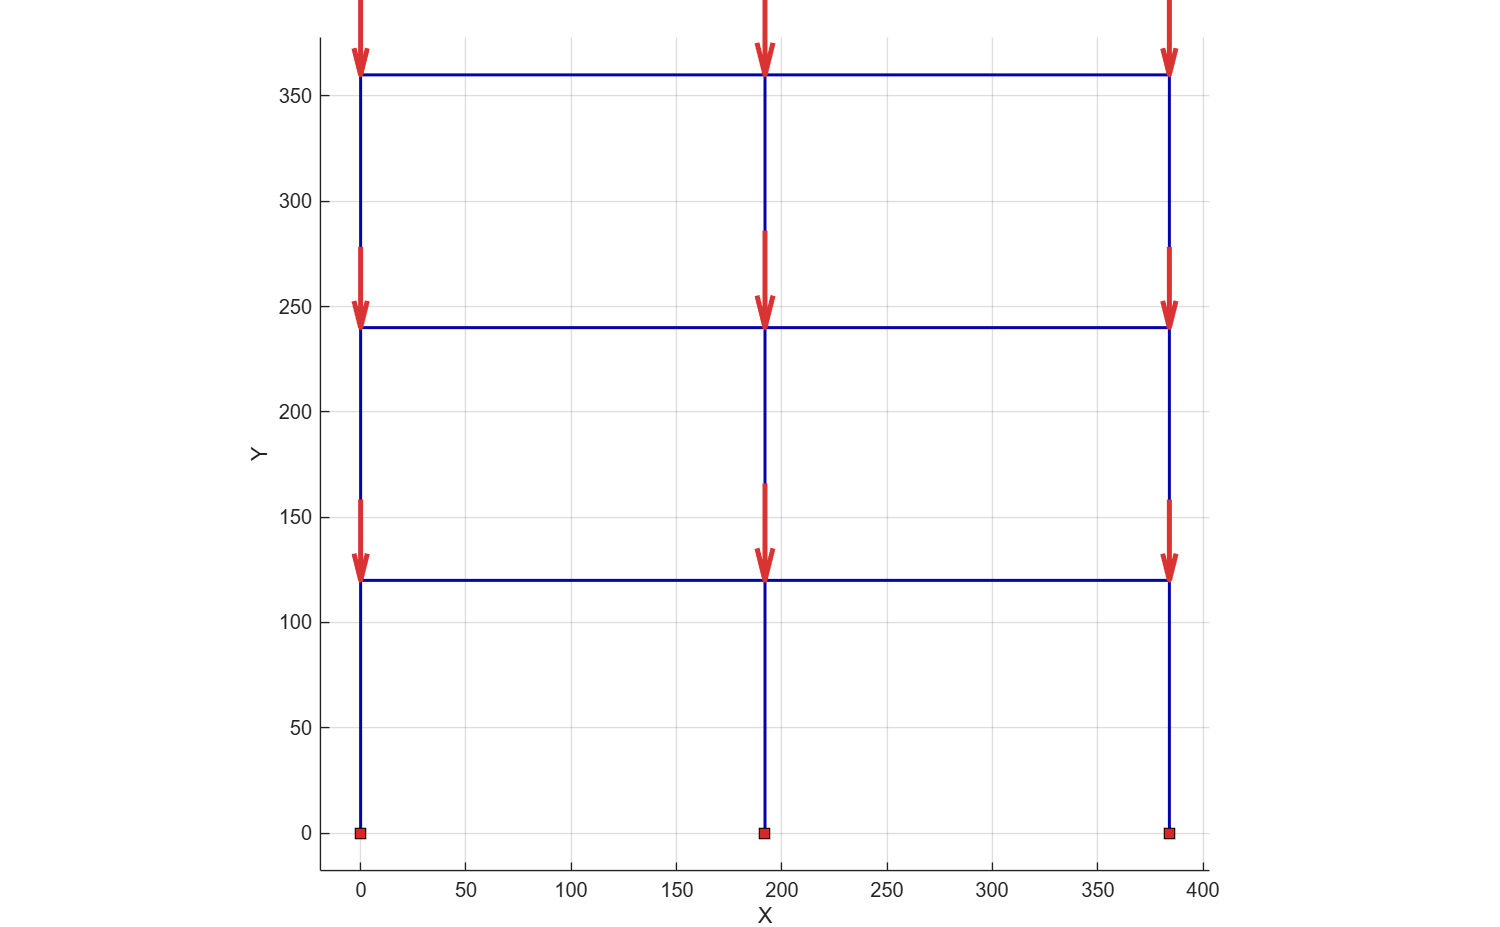

opts = struct();
opts.loads.showNodal = true;
opts.loads.lineWidth = 2.5;
opts.loads.scale = 1.5;

opsMat.vis.plotModel(opts=opts);

### Visualize the eigen analysis

This section configures and runs the analysis. The solver, constraints, convergence test, and step size should be read together because they control numerical robustness.

eigenData = opsMat.post.getEigenData(numModes=2, solver='-genBandArpack');
disp(eigenData)

                    ModeTags: [2×1 double]
                  ModalProps: [1×1 struct]
                EigenVectors: [1×1 struct]
    InterpolatedEigenVectors: [1×1 struct]
                   ModelInfo: [1×1 struct]



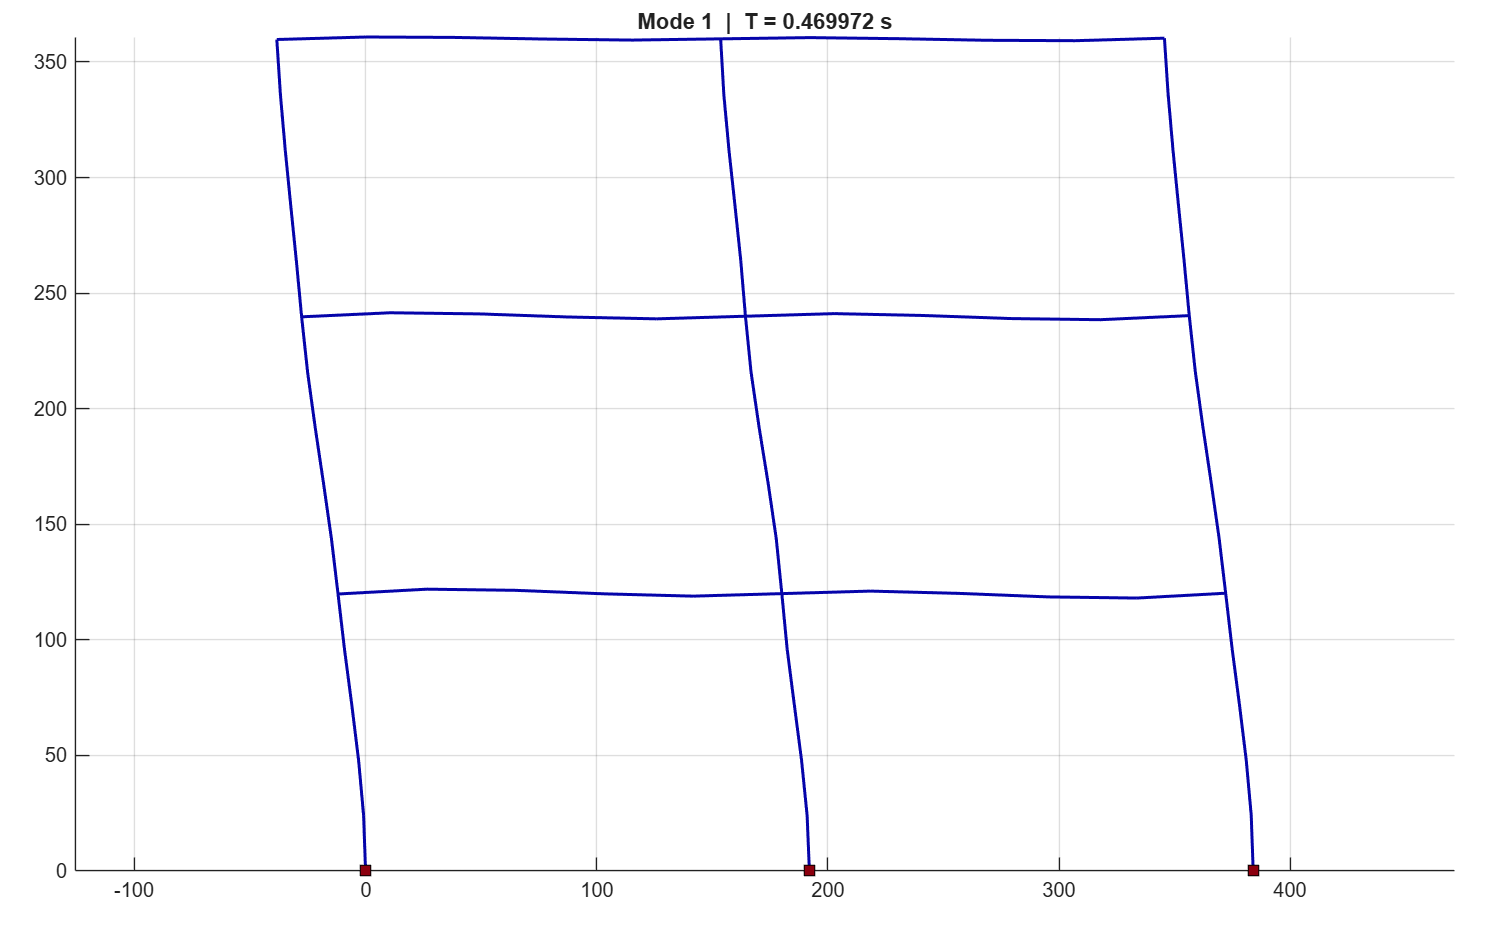

opsMat.vis.plotEigen(1, eigenData);

### `Perform gravity analysis`

This section applies the actions on the model. The load pattern and scaling determine what response the analysis will try to reproduce.

NstepsGrav = 10;

ops.system('BandGEN');
ops.numberer('Plain');
ops.constraints('Plain');
ops.integrator('LoadControl', 1.0 / NstepsGrav);
ops.algorithm('Newton');
ops.test('NormUnbalance', 1e-8, 10);
ops.analysis('Static');

% Perform gravity analysis
data = zeros(NstepsGrav + 1, 2);
for j = 1:NstepsGrav
    ops.analyze(1);
    data(j+1, 1) = ops.nodeDisp(31, 2);
    data(j+1, 2) = ops.getLoadFactor(1) * 5;
end

ops.loadConst('-time', 0.0);

disp('Gravity analysis complete');

Gravity analysis complete



ops.wipeAnalysis();

### `Perform pushover analysis`

This section configures and runs the analysis. The solver, constraints, convergence test, and step size should be read together because they control numerical robustness.


disp('<<<< Running Pushover Analysis >>>>');

<<<< Running Pushover Analysis >>>>



% Create load pattern for pushover analysis
ops.pattern('Plain', 2, 1);

ops.load(11, 1.61, 0.0, 0.0);
ops.load(21, 3.22, 0.0, 0.0);
ops.load(31, 4.83, 0.0, 0.0);

ControlNode = 31;
ControlDOF  = 1;
MaxDisp     = 0.15 * H_story;
DispIncr    = 0.1;
NstepsPush  = floor(MaxDisp / DispIncr);

ops.system('ProfileSPD');
ops.numberer('Plain');
ops.constraints('Plain');
ops.integrator('DisplacementControl', ControlNode, ControlDOF, DispIncr);
ops.algorithm('Newton');
ops.test('NormUnbalance', 1e-8, 10);
ops.analysis('Static');

PushDataDir = 'output_data';
if exist(PushDataDir, 'dir') ~= 7
    mkdir(PushDataDir);
end

ops.recorder('Node', ...
    '-file', fullfile(PushDataDir, 'Node2React.out'), ...
    '-closeOnWrite', ...
    '-node', 2, '-dof', 1, 'reaction');

ops.recorder('Node', ...
    '-file', fullfile(PushDataDir, 'Node31Disp.out'), ...
    '-closeOnWrite', ...
    '-node', 31, '-dof', 1, 'disp');

ops.recorder('Element', ...
    '-file', fullfile(PushDataDir, 'BeamStress.out'), ...
    '-closeOnWrite', ...
    '-ele', 102, 'section', 4, 'fiber', 'stressStrain');

% Perform pushover analysis
dataPush = zeros(NstepsPush + 1, 5);

for j = 1:NstepsPush
    ok = ops.analyze(1);
    if ok ~= 0
        warning('Pushover analysis failed at step %d.', j);
        dataPush = dataPush(1:j, :);
        break;
    end

    dataPush(j+1, 1) = ops.nodeDisp(31, 1);

    ops.reactions();
    dataPush(j+1, 2) = ops.nodeReaction(1, 1) + ...
        ops.nodeReaction(2, 1) + ...
        ops.nodeReaction(3, 1);
end

### Plot Results

This section collects the quantities of interest from the analysis. The recorded data are used later for plotting, verification, or post-processing.

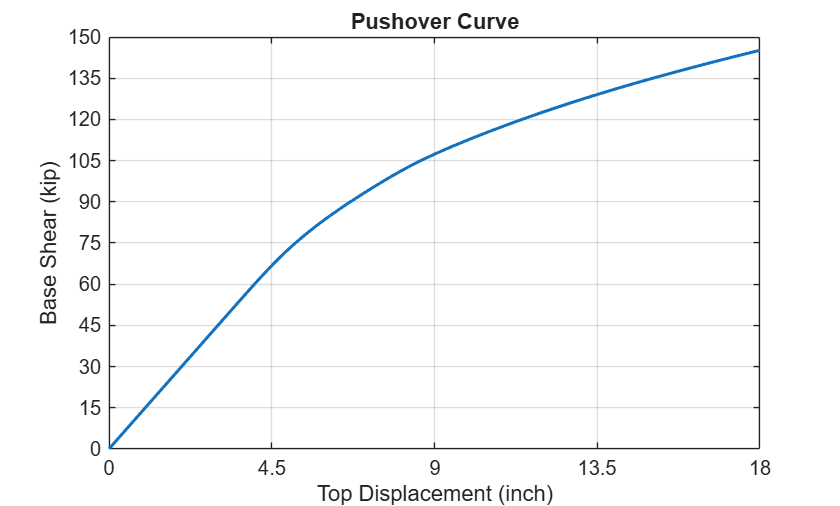

figure;
plot(dataPush(:,1), -dataPush(:,2), 'LineWidth', 1.5);
xlim([0, MaxDisp]);
xticks(linspace(0, MaxDisp, 5));

yMax = max(-dataPush(:,2));
if yMax > 0
    yticks(0:15:150);
end

grid on;
xlabel('Top Displacement (inch)');
ylabel('Base Shear (kip)');
title('Pushover Curve');